# Main

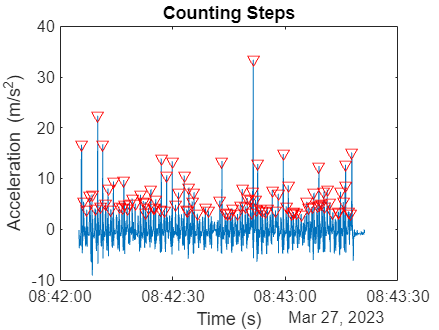

clc, clear;
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks

%https://uk.mathworks.com/help/signal/ug/human-activity-recognition-using-signal-feature-extraction-and-machine-learning.html
%Look into the link above for activity recognition etc instead of what I
%have done

% Loads mat file into workspace and stores its data
fileName = "Step100.mat";
fileData = openFile(fileName);
walk_dataAccel = fileData.Acceleration;
walk_dataOrien = fileData.Orientation;
clear fileData fileName;

% Loads mat file into workspace and stores its data
fileName = "Sitting1.mat";
fileData = openFile(fileName);
sit_dataAccel = fileData.Acceleration;
sit_dataOrien = fileData.Orientation;
clear fileData fileName;

fileName = "running.mat";
fileData = openFile(fileName);
run_dataAccel = fileData.Acceleration;
run_dataOrien = fileData.Orientation(1:end-1,:);
clear fileData fileName;

% fileName = "rowing machine.mat";
% fileData = openFile(fileName);
% row_dataAccel = fileData.Acceleration;
% row_dataOrien = fileData.Orientation;
% clear fileData fileName;

fileName = "Drive1.mat";
fileData = openFile(fileName);
drive_dataAccel = fileData.Acceleration;
drive_dataOrien = fileData.Orientation;
clear fileData fileName;

% Smooth out data
[walk_dataAccel, walk_dataOrien] = DataClean(walk_dataAccel, walk_dataOrien);
[sit_dataAccel,sit_dataOrien] = DataClean(sit_dataAccel, sit_dataOrien);
[run_dataAccel,run_dataOrien] = DataClean(run_dataAccel, run_dataOrien);
% [row_dataAccel, row_dataOrien] = DataClean(row_dataAccel, row_dataOrien);
[drive_dataAccel,drive_dataOrien] = DataClean(drive_dataAccel, drive_dataOrien);

%Create a function for Step Counter and plotting it
stepCount = steps(walk_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 102

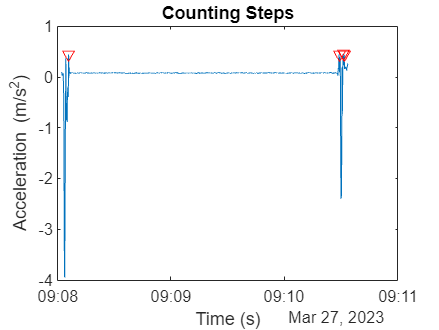

clear stepCount;

stepCount = steps(sit_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 4

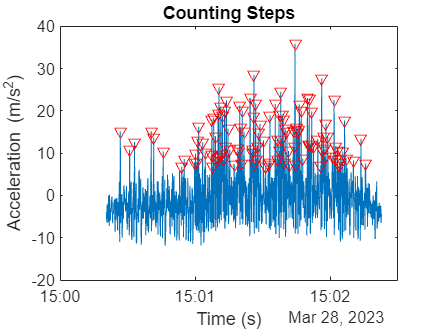

clear stepCount;

stepCount = steps(run_dataAccel);

fprintf('Number of Steps: %.15g', stepCount);

Number of Steps: 112

clear stepCount;


% Walking = 0, Sitting = 1, Running = 2, Driving = 3
classes = ["Walking", "Sitting", "Running", "Driving"];
% Extract Features from timetables
featureData = extractFeat(walk_dataAccel,walk_dataOrien);
Classification = categorical(zeros(height(featureData),1));
extractedData = addvars(featureData,Classification);

clear featureData Classification;

featureData = extractFeat(sit_dataAccel,sit_dataOrien);
Classification = categorical(ones(height(featureData),1));
featureData = addvars(featureData,Classification);
extractedData = [extractedData; featureData];
clear featureData;

featureData = extractFeat(run_dataAccel,run_dataOrien);
Classification = categorical(repmat(2,height(featureData),1));
featureData = addvars(featureData,Classification);
extractedData = [extractedData; featureData];
clear featureData;




featureData = extractFeat(drive_dataAccel,drive_dataOrien);
Classification = categorical(repmat(3,height(featureData),1));
featureData = addvars(featureData,Classification);
extractedData = [extractedData; featureData];
clear featureData;


goodData = rmmissing(extractedData, 'DataVariables',{'Xaccel', 'Yaccel','Zaccel'});
goodData = timetable2table(goodData);
cv= cvpartition(size(goodData,1),'Holdout', 0.3);
idx = cv.test;
dataTrain = extractedData(~idx,:);
dataTest = extractedData(idx,:);
